Run graphics export and animation from the Command Window; Live Editor export can block. Run runMeFirst in the package root, then add the chosen example folder or make it Current Folder before calling a .m example by name.

# gearRack — Basic rack (v21)

gears v21 — Public interface guide.

Run runMeFirst once from the package root before running this Live Script. The bundled draw*/gk* routines and int2crv are private implementation helpers in classes/private; do not add that folder to the MATLAB path.

See examples/README.md for the scripts. Relative outputs use Current Folder; output methods create missing parent folders. Cached Live Script outputs are retained from the supplied archive and have not been regenerated. Run sections in order for current results.

Use public plot/animate/print methods. For plots: 'title',on/off/1/0/true/false; 'save',filename or 'save',[] for the default JPG. Names without '-' are preferred; the old prefix remains accepted.

Create a standard-height basic rack. Its parameters m, alpha and c are read-only. Set tip shortening on a gear object, not on this rack.

## Description

A value object representing a standard-height generating rack. Module m, pressure angle alpha and clearance coefficient c are read-only. Tip shortening u belongs to each gear, never to the rack.

## ** Properties **

**        m            ** - Module

**        alpha      ** - Pressure angle in degrees

**        c - dimensionless manufacturing clearance coefficient**

## **Creation**

**rack = gearRack(m,'alpha',20,'c',0.167)**

    Input:

        m - normal module; its unit determines all lengths

    Optional input pairs:

'alpha',alpha - normal pressure angle in degrees; default 20. The rack also enforces the clearance bound stated in help gearRack.

'c',c - dimensionless clearance coefficient; default 0.167. Clearance length is m*c.

## **User methods**

print(rack) prints to the Command Window; print(rack,filename) writes a text file and creates missing parent folders. Use millimetres to match printed length labels. The clearance coefficient c is dimensionless and is printed without a unit; its corresponding rack clearance length is m*c.

**plot(rack,'fig',number,'title',false,'save',filename) draws the normal rack with dimensions. Omit fig to create a new figure.**

gearGenerating(rack,z,...) displays successive rack positions in one static figure. It does not animate the rack.

    Input:

z - integer number of teeth, z>1.

    Optional input:

        'save',filename or 'save',[] - named/default JPG; 'title',false suppresses the heading

    Optional input name-value pairs:

        'x',x - profile shift used for the generation display

        'beta',beta - helix angle in degrees

## **    Examples**

% Run runMeFirst once before this Live Script; private helpers are bundled.

% Outputs use pwd. No output directories are created by setup.
assert(~isempty(which('gear')),'Run runMeFirst first.');


## **Example 1**

m = 3;
a = gearRack(m)

a =   gearRack with properties:

    alpha: 20
        m: 3
        c: 0.1670


print(a)

Gear rack data
                                    Module:            3.0000       mm
                            Pressure angle:            20:00:00
                       Tip tooth clearance:            0.1670       mm
Calculated parameters
                              Filet radius:            0.7614       mm
                                     Point:      xx          yy 
                                        #1:      0.0000      3.0000 mm
                                        #2:      1.2643      3.0000 mm
                                        #3:      3.4481     -3.0000 mm
                                        #4:      4.1636     -3.5010 mm
                             Fillet center:      4.1636     -2.7396 mm
                                   Segment:            Length
                                        #1:            1.2643       mm
                                        #2:            6.3851       mm
                                        #3:            0.9303 

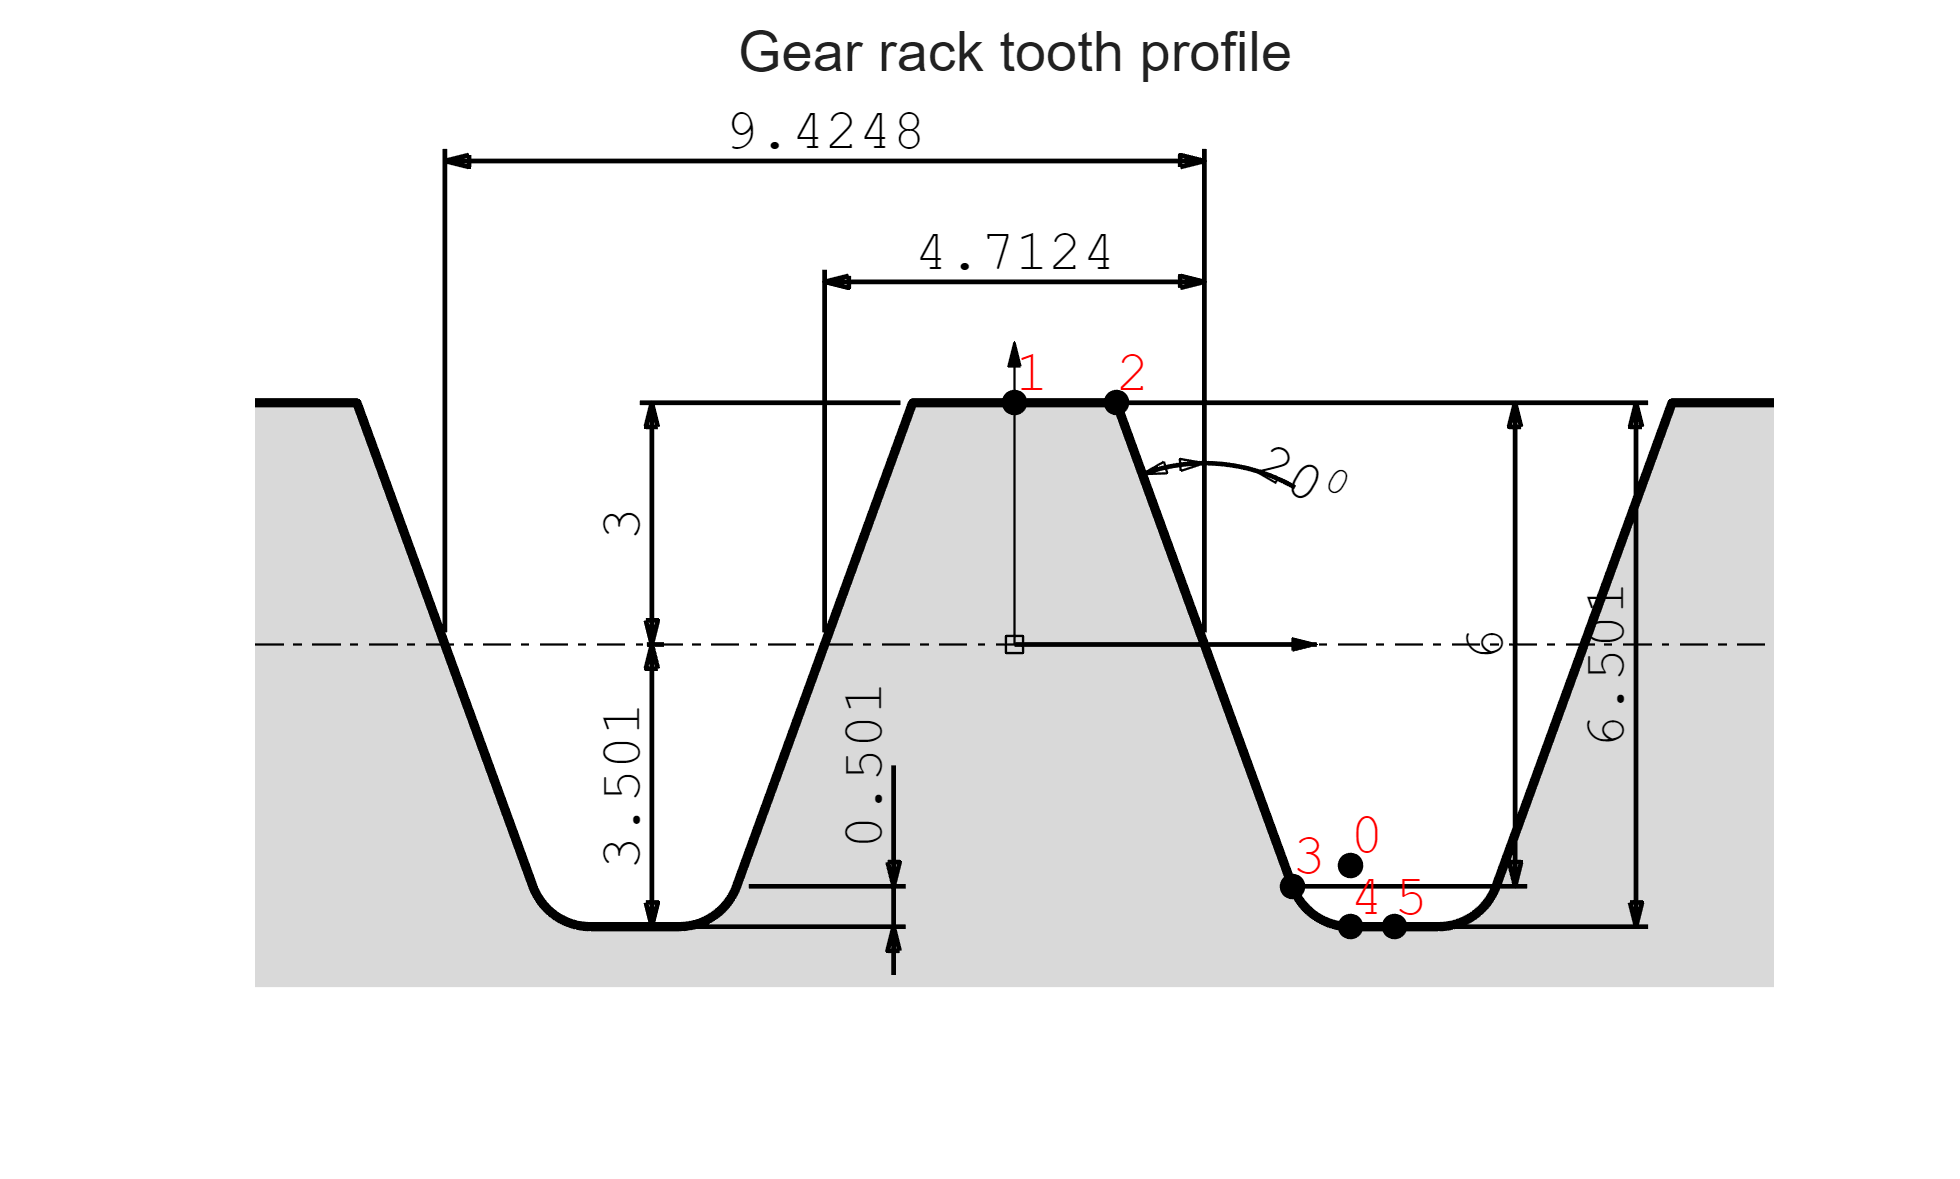

plot(a)

## **Example 2**

alpha=15.7;
m = 3;
a = gearRack(m,'alpha',alpha); % basic rack has no u option
print(a)

Gear rack data
                                    Module:            3.0000       mm
                            Pressure angle:            15:42:00
                       Tip tooth clearance:            0.1670       mm
Calculated parameters
                              Filet radius:            0.6869       mm
                                     Point:      xx          yy 
                                        #1:      0.0000      3.0000 mm
                                        #2:      1.5129      3.0000 mm
                                        #3:      3.1995     -3.0000 mm
                                        #4:      3.8607     -3.5010 mm
                             Fillet center:      3.8607     -2.8141 mm
                                   Segment:            Length
                                        #1:            1.5129       mm
                                        #2:            6.2325       mm
                                        #3:            0.8907 

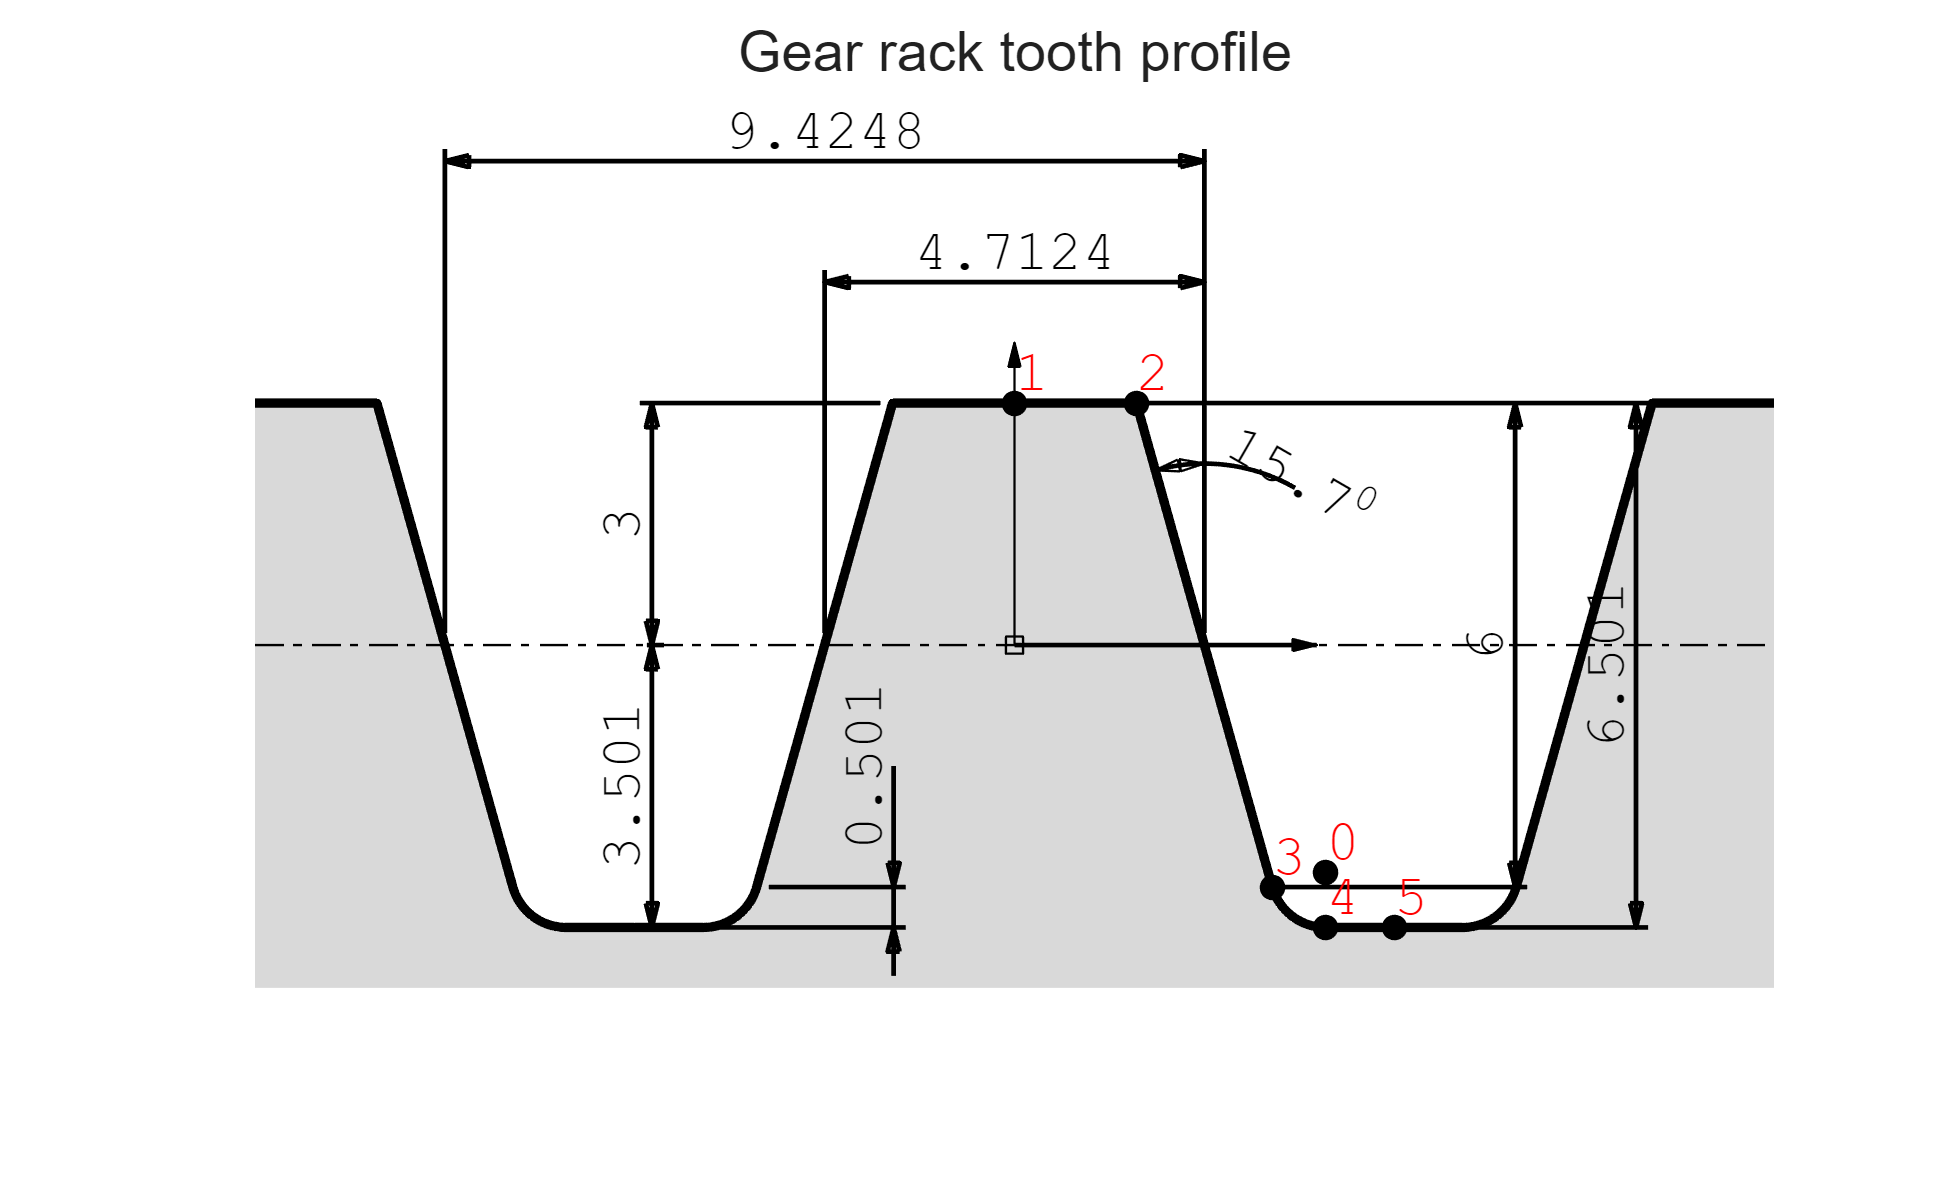

plot(a)

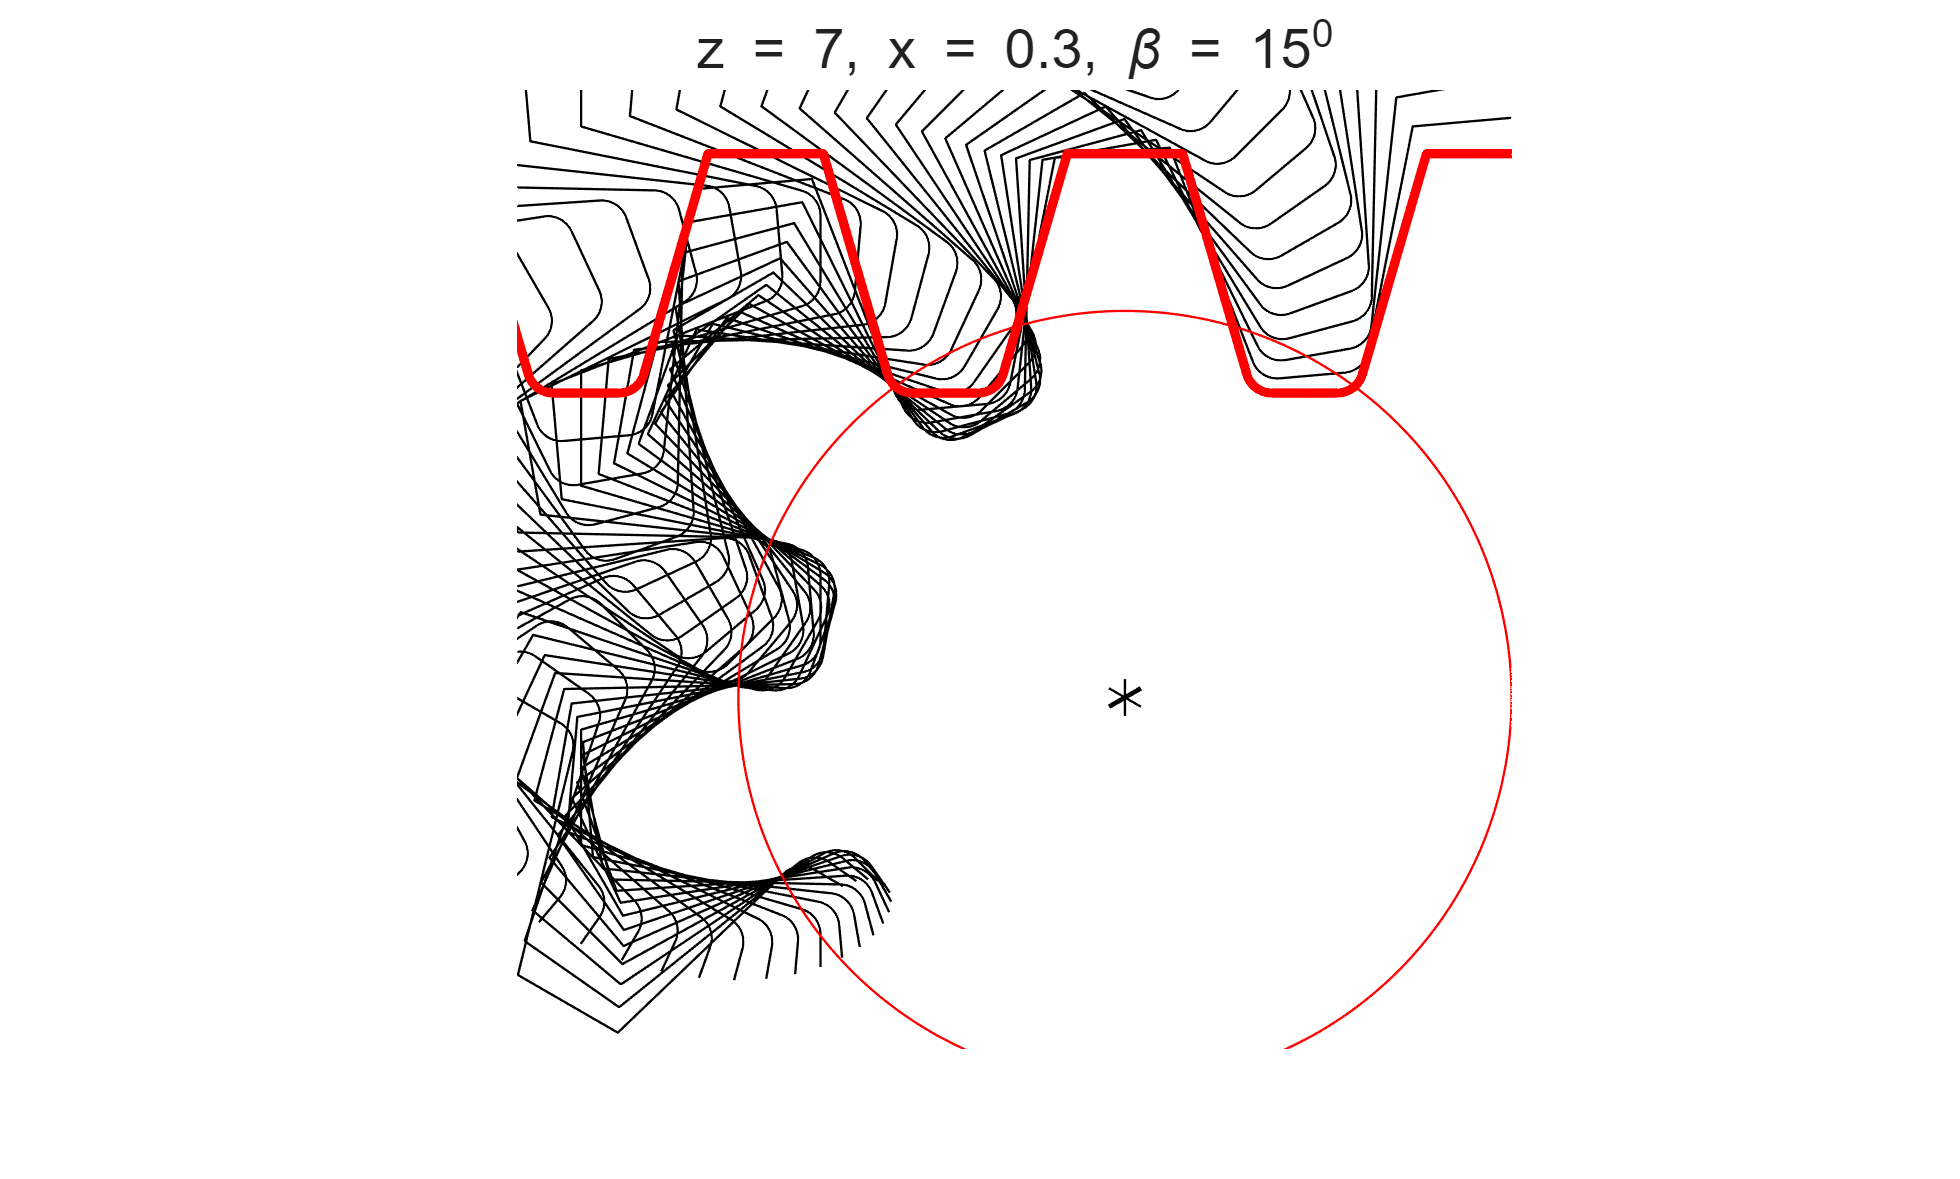

x = 0.3;
z = 7;
gearGenerating(a,z,'x',x,'beta',15)

gearGenerating(a,z,'x',x,'beta',15)

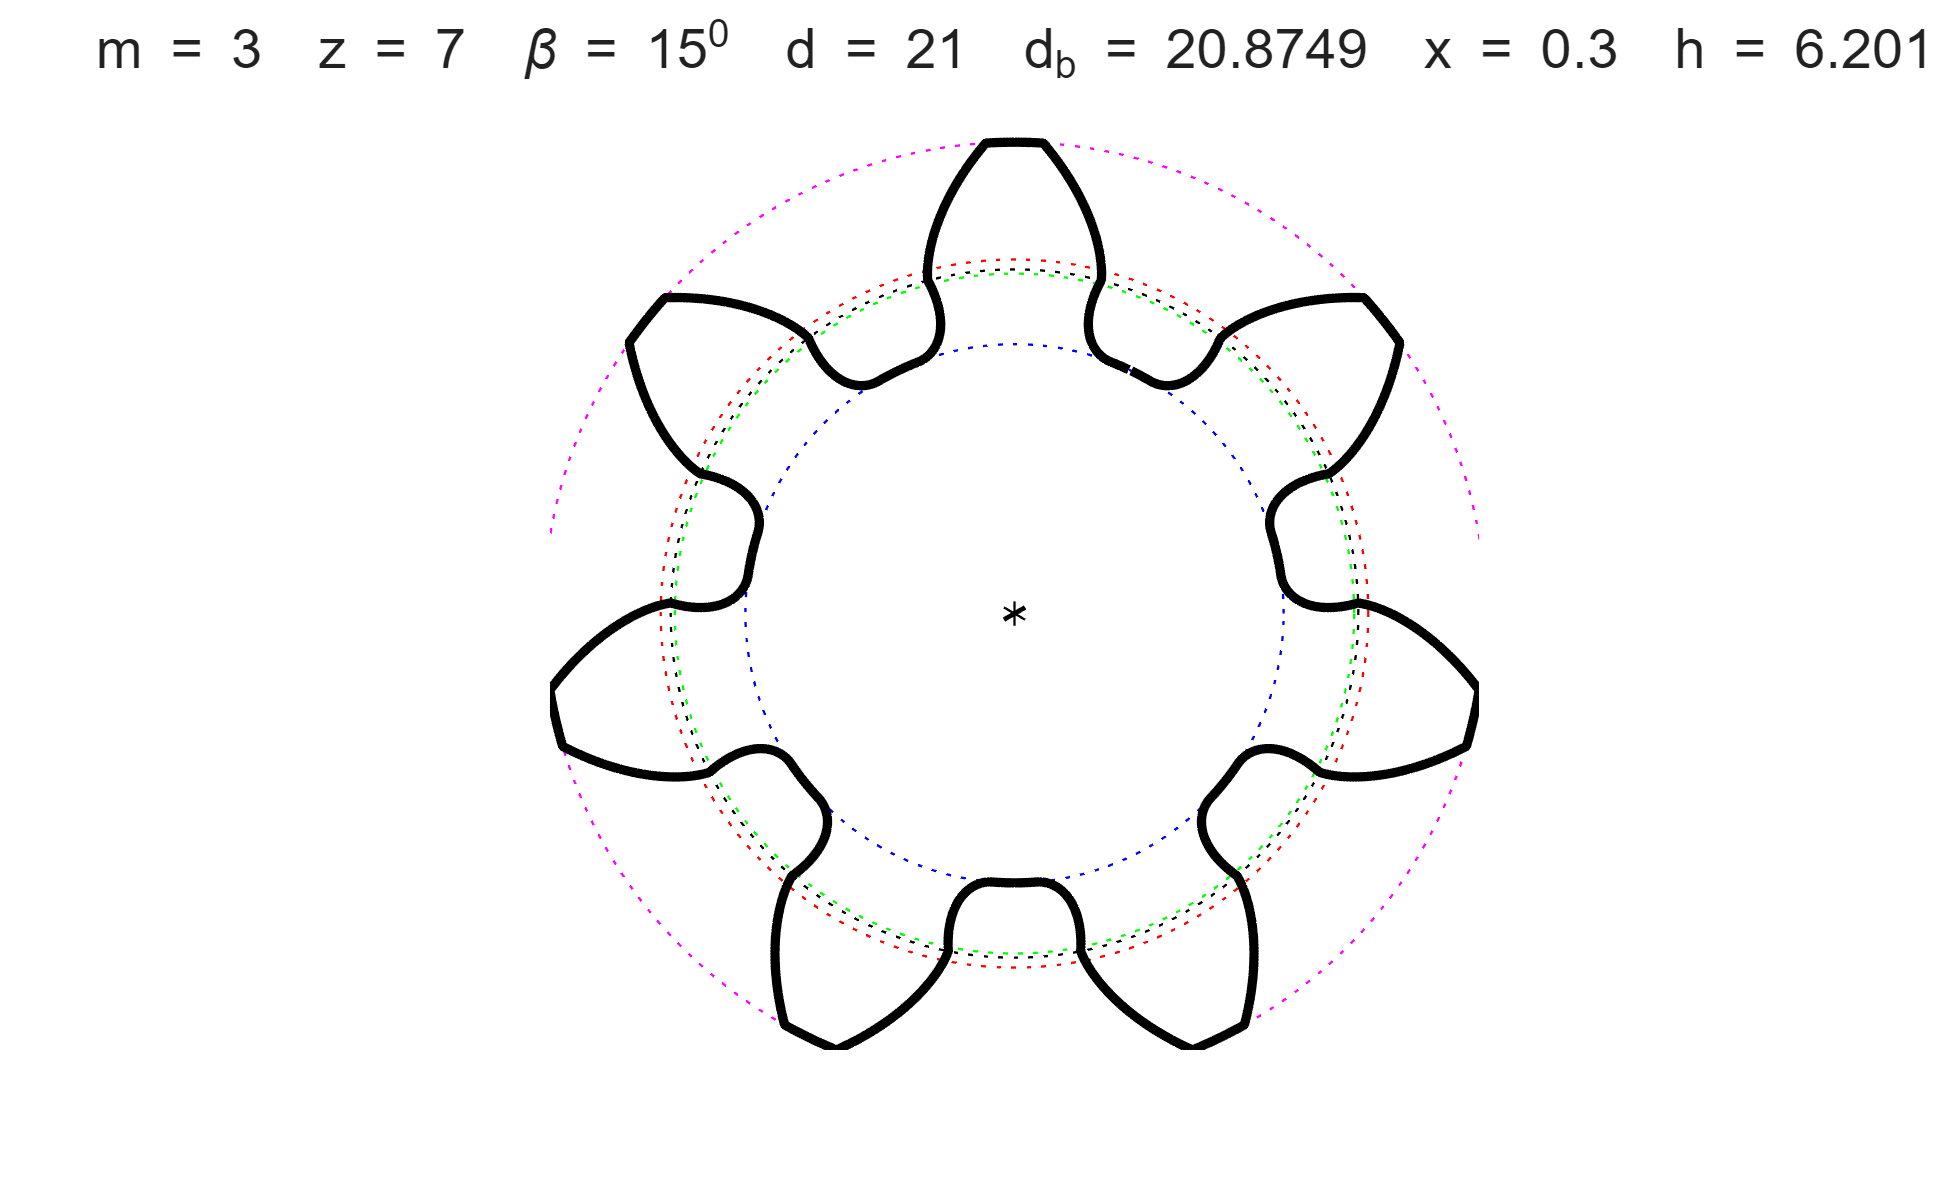

% Shortening is set on the gear only; a remains unchanged.
g = gear(a,z,'x',x,'beta',15,'u',0.9);
plot(g)